Allows for computation of "muscle force fractions"$f^L \left({\overset{~}{l} }^M \right)$and $f^v \left({\overset{~}{i} }^M \right)$for normalized muscle fiber length and velocities

Requires inputs for normalized muscle fiber length (nl_M) , tendon length (nl_T), muscle fiber velocity (ni)

function z = Thelen2003_Force_Fractions(nlM, nlT, ni, muscle_props)
z = [nlM,nlT,ni];
F_iso_max = muscle_props(1);
l_M_opt = muscle_props(2);
l_T_slack = muscle_props(3);

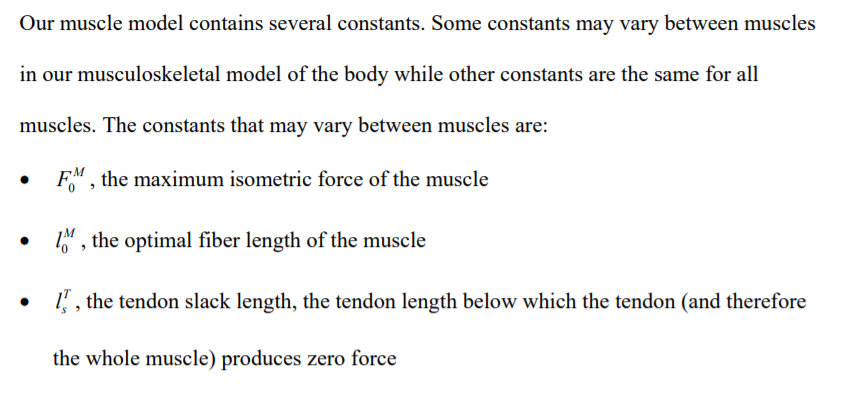

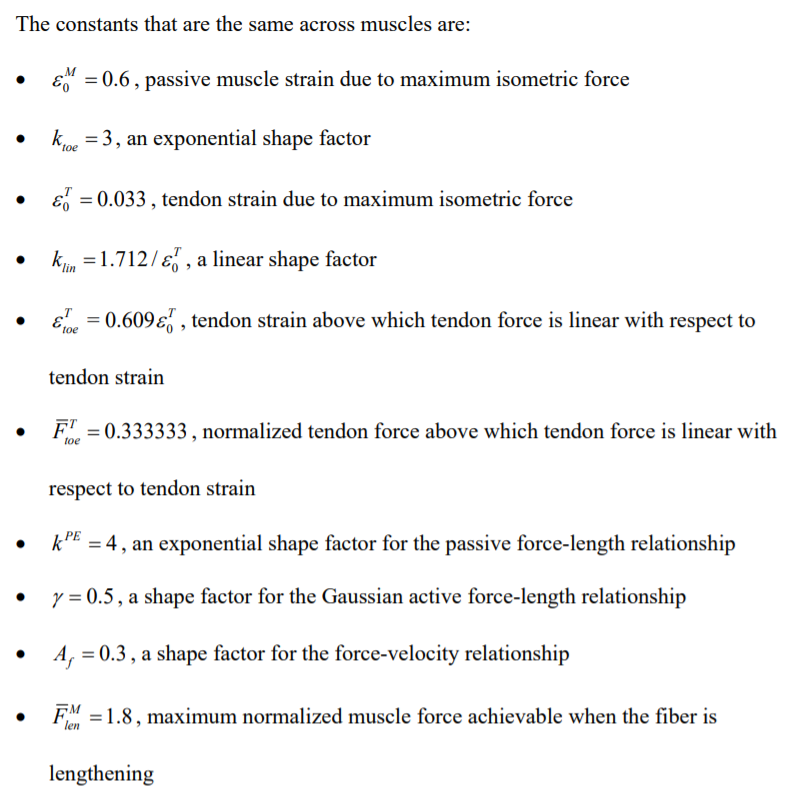

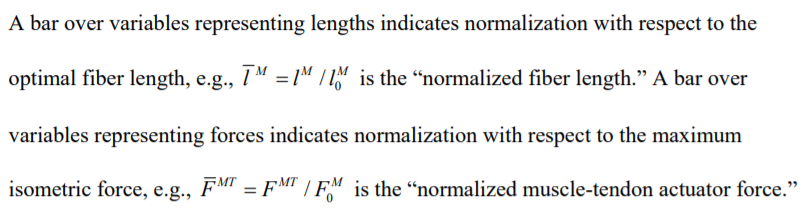

% define constants across all muscles
eM_0 = 0.6; % passive muscle strain due to maximum isometric force
k_toe = 3; % an exponential shape factor
eT_toe = 0.033; % tendon strain due to maximum isometric force
k_lin = 1.712/eT_toe; % a linear shape factor
nFT_toe = 1/3; % normalized tendon force above which tendon force is linear with respect to tendon strain
k_PE = 4; % an exponential shape factor for the passive force-length relationship
gamma = 0.5; % a shape factor for the Gaussian active force-length relationship
A_f = 0.3; % a shape factor for the force-velocity relationship
norm_F_M_len = 1.8; % maximum normalized muscle force achievable when the fiber is lengthening

nl_Ts = l_T_slack/l_M_opt; % normalized tendon slack length
strain_T = (nlT - nl_Ts)/nl_Ts;

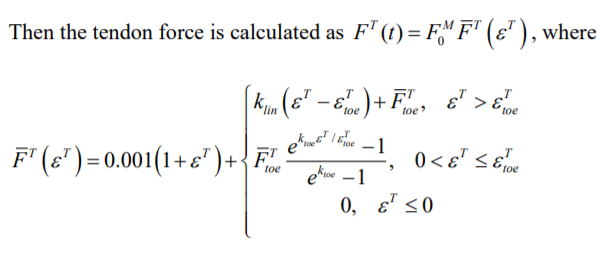

nF_T = @(eT) 0.001*(1+eT) + (eT > eT_toe)*(k_lin*(eT-eT_toe)+nFT_toe) + ...
                  (0 < eT & eT <= eT_toe)*(nFT_toe*((exp(k_toe*eT/eT_toe) - 1)/(exp(k_toe) - 1))) + ...
                                    (eT <= 0)*0;

Recall that $F^{MT} \left(t\right)=F^T \left(t\right)$ since muscle and tendon are in series

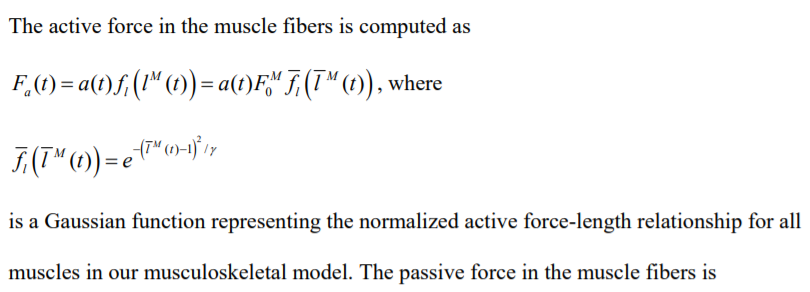

nF_L = @(l) exp(-(l-1)^2/gamma);

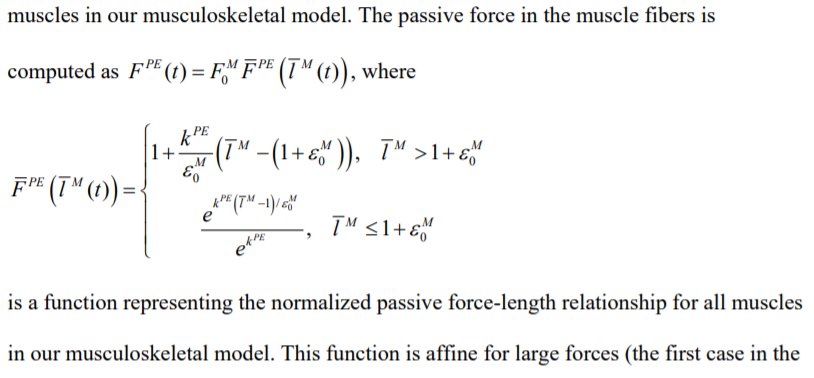

nF_PE = @(l) (l > (1+eM_0))*(1 + k_PE/eM_0 * (l - (1 + eM_0))) + ...
             (l <=(1+eM_0))*(exp(k_PE*(l - 1)/eM_0) / exp(k_PE));



end